clearvars;
dir = 'results/optimization/'

dir = 'results/optimization/'

outdir = 'results/optimization_results/'

outdir = 'results/optimization_results/'

load([dir,'optimization_results.mat']);

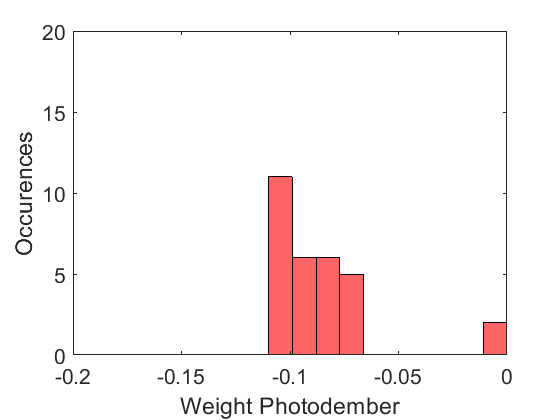

weight_pd = [optimization_combined(1:30).weight_pd];
H = histogram(weight_pd,10,'FaceColor',[1,0,0]);
set(gca,'FontSize',16);
xlim([-0.2,0]);
ylim([0,20]);
xlabel('Weight Photodember');
ylabel('Occurences');
exportgraphics(gca,[outdir,'pdweight.png'],'Resolution',300);

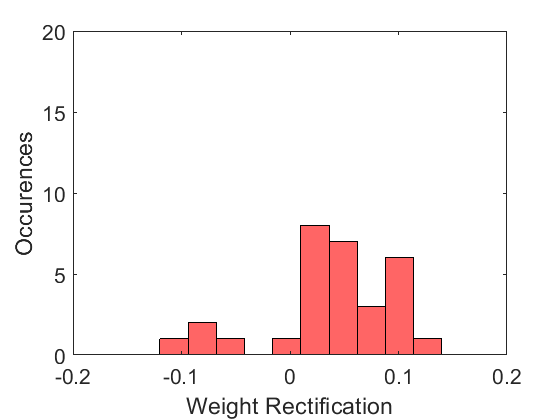

weight_or = [optimization_combined(1:30).weight_or];
H = histogram(weight_or,10,'FaceColor',[1,0,0]);
set(gca,'FontSize',16);
xlim([-0.2,0.2]);
ylim([0,20]);
xlabel('Weight Rectification');
ylabel('Occurences');
exportgraphics(gca,[outdir,'orweight.png'],'Resolution',300);

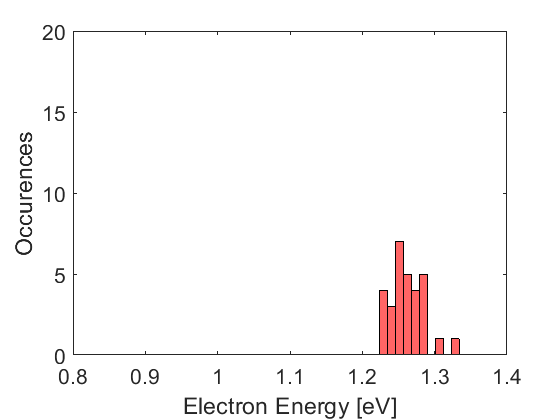

electron_energy = [optimization_combined(1:30).electron_tot_energy];
H = histogram(electron_energy,10,'FaceColor',[1,0,0]);
set(gca,'FontSize',16);
xlim([0.8,1.4]);
ylim([0,20]);
xlabel('Electron Energy [eV]');
ylabel('Occurences');
exportgraphics(gca,[outdir,'electronenergy.png'],'Resolution',300);

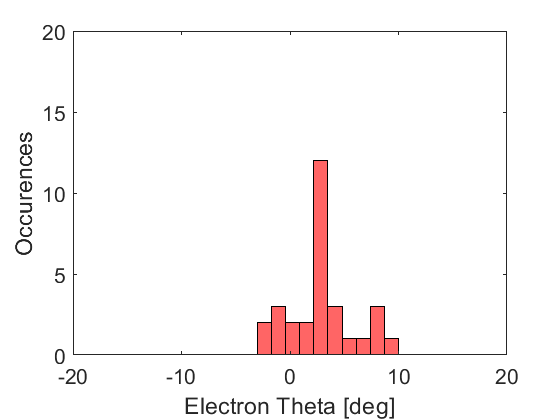

electron_theta = [optimization_combined(1:30).electron_theta_deg];
H = histogram(electron_theta,10,'FaceColor',[1,0,0]);
set(gca,'FontSize',16);
xlim([-20 20]);
ylim([0,20]);
xlabel('Electron Theta [deg]');
ylabel('Occurences');
exportgraphics(gca,[outdir,'electronthetay.png'],'Resolution',300);

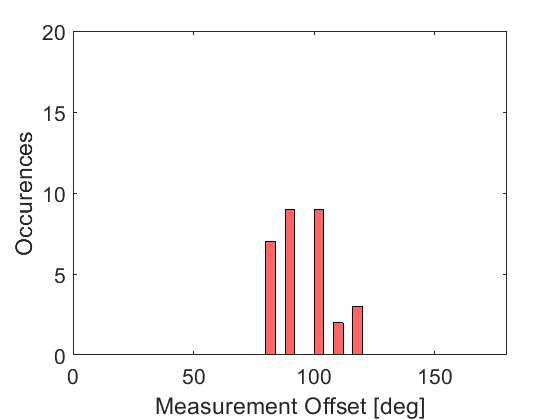

offset = [optimization_combined(1:30).offset];
H = histogram(offset,10,'FaceColor',[1,0,0]);
set(gca,'FontSize',16);
xlim([0 180]);
ylim([0,20]);
xlabel('Measurement Offset [deg]');
ylabel('Occurences');
exportgraphics(gca,[outdir,'offset.png'],'Resolution',300);

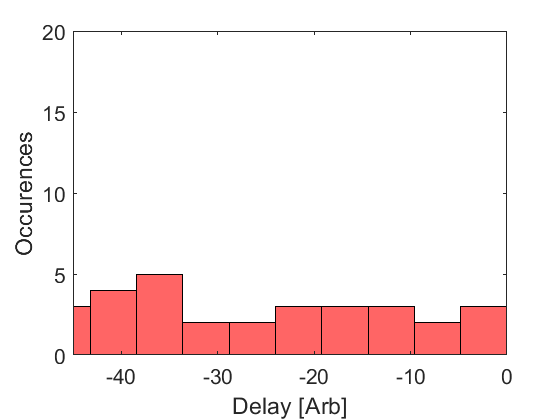

delay = [optimization_combined(1:30).delay];
H = histogram(delay,10,'FaceColor',[1,0,0]);
set(gca,'FontSize',16);
xlim([-45 0]);
ylim([0,20]);
xlabel('Delay [Arb]');
ylabel('Occurences');
exportgraphics(gca,[outdir,'delay.png'],'Resolution',300);